**BMFLC Template**

Part 1: Create signal

t = 0:0.001:120;    % time vector
N = length(t);      % signal length
nu = 0.0001;         % adaptive gain

% To Do:

Mp_i = 0.1*sin(30*t)+0.1*sin(35*t)+0.1*cos(30*t)+0.1*cos(35*t);
Mp_v = sin(t)+2*sin(2*t)+3*sin(3*t)+cos(t)+2*cos(2*t)+3*cos(3*t);
Mp = Mp_i + Mp_v;

Part 2: Create frequency range

% To Do:

w_a = 0;    % minimum freq
w_b = 35;    % maximum freq
beta = 36;
freq_vec = linspace(w_a,w_b,beta);

Part 3: Create placeholder vectors

Mp_hat = zeros(1,N);
theta = zeros(1,2*beta);
phi = zeros(1,2*beta);

Part 4: Estimate Mp_hat

for i = 1:N
    for j = 1:beta
        % To Do:
        
        phi(j) = sin((w_a+freq_vec(j))*t(i));         % sine component
        phi(j+beta) = cos((w_a+freq_vec(j))*t(i));    % cosine component
    end
    Mp_hat(i) = phi*theta';
    Err = Mp(i) - Mp_hat(i);
    theta = theta + 2*nu*phi*Err;              % update theta using error
end

Part 5: Plot Mp_hat and Mp on the same figure

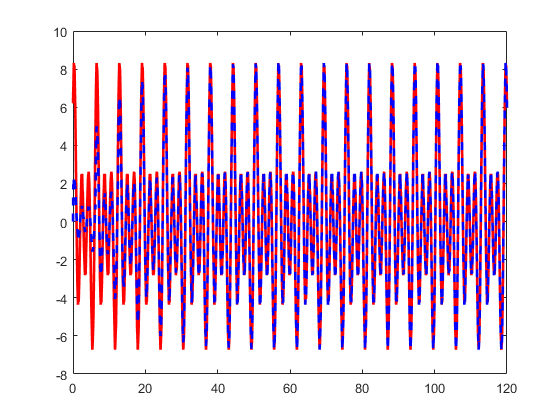

% To Do:
figure(1)
plot(t,Mp,'r',t,Mp_hat,'b--','linewidth',2)

Part 6: Extract the voluntary and involuntary component

*Hint: the final theta contains the weights for the fourier series. The first half contains the weights ('*$\lambda$*') for the sine components, and the second half contains the weight for the cosing components ('*$\vartheta$*'). These are ordered from lowest frequency to the highest frequency.*

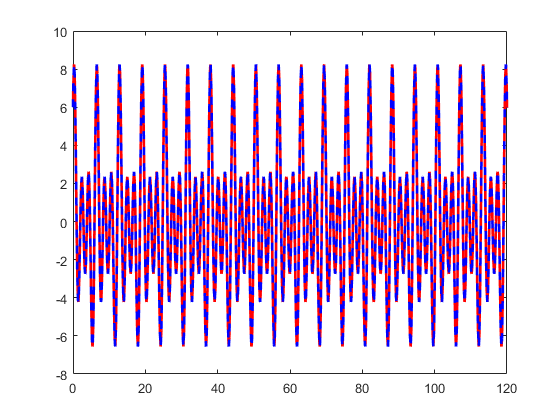

Mp_v_hat = zeros(1,N);

w_cutoff = 3;
idx = length(find(w_cutoff >= freq_vec));
lambda = theta(1:idx);
vartheta = theta(beta+1:beta+idx);
theta_v = [lambda vartheta];
phi_v = zeros(1,2*idx);

for i = 1:N
    for j = 1:idx
        phi_v(j) = sin((w_a+freq_vec(j))*t(i));         % sine component
        phi_v(j+idx) = cos((w_a+freq_vec(j))*t(i));    % cosine component
    end
    Mp_v_hat(i) = phi_v*theta_v';
end


figure(2)
plot(t,Mp_v,'r',t,Mp_v_hat,'b--','linewidth',2)